# Simulink full control system simulation

We can also try to simulate our model in simulink. This provides a nice graphical overview of our system.

We need to load some data

clear

addpath ./data
addpath ./functions

modelName = fullfile(pwd,'models','SOF@18d66s_FG.mat');
model = load(modelName);

targetName = fullfile(pwd,'models','EOF@116d46s_FG.mat');
target = load(targetName);

load VS_contr.mat  VS_contr
load PF_contr.mat  PF_contr
load Ip_contr.mat  Ip_contr
load shape_contr.mat SHP_contr iGap

and define the reference signals for our system.

i_xp = get_y_idx(model.y_type,{'Rbound','Zbound'},1);
i_gap = get_y_idx(model.y_type,'Gap');
i_gap = i_gap(iGap);

targetGaps = target.y_np(i_gap);
initialGaps = model.y_np(i_gap);
dGap = targetGaps-initialGaps;

targetXp = target.y_np(i_xp);
initialXp = model.y_np(i_xp);
dXp = targetXp-initialXp;
dXp = dXp + [0.01; 0]; % move the x point a little

dIp = 0; % keep Ip constant     

% We use the equilibrium currents as feedforwards
clear I_FF
I_FF.time = [0 1 9 12]';
I1 = model.y_np(1:10,1);
I2 = target.y_np(1:10,1);
I_FF.signals.values = [I1 I1 I1 I1]';

% And here is the shape reference
shp_ref.time = I_FF.time;
dShp = [dGap; dXp];
shp_ref.signals.values = repmat([initialGaps; initialXp]',4,1) + [dShp*0 dShp*0 dShp dShp]';

Here is a full simulation scheme.

cd ./simulink
load SOF18d66_setup.mat
open SOF18d66.slx

Let's run it and see what happens

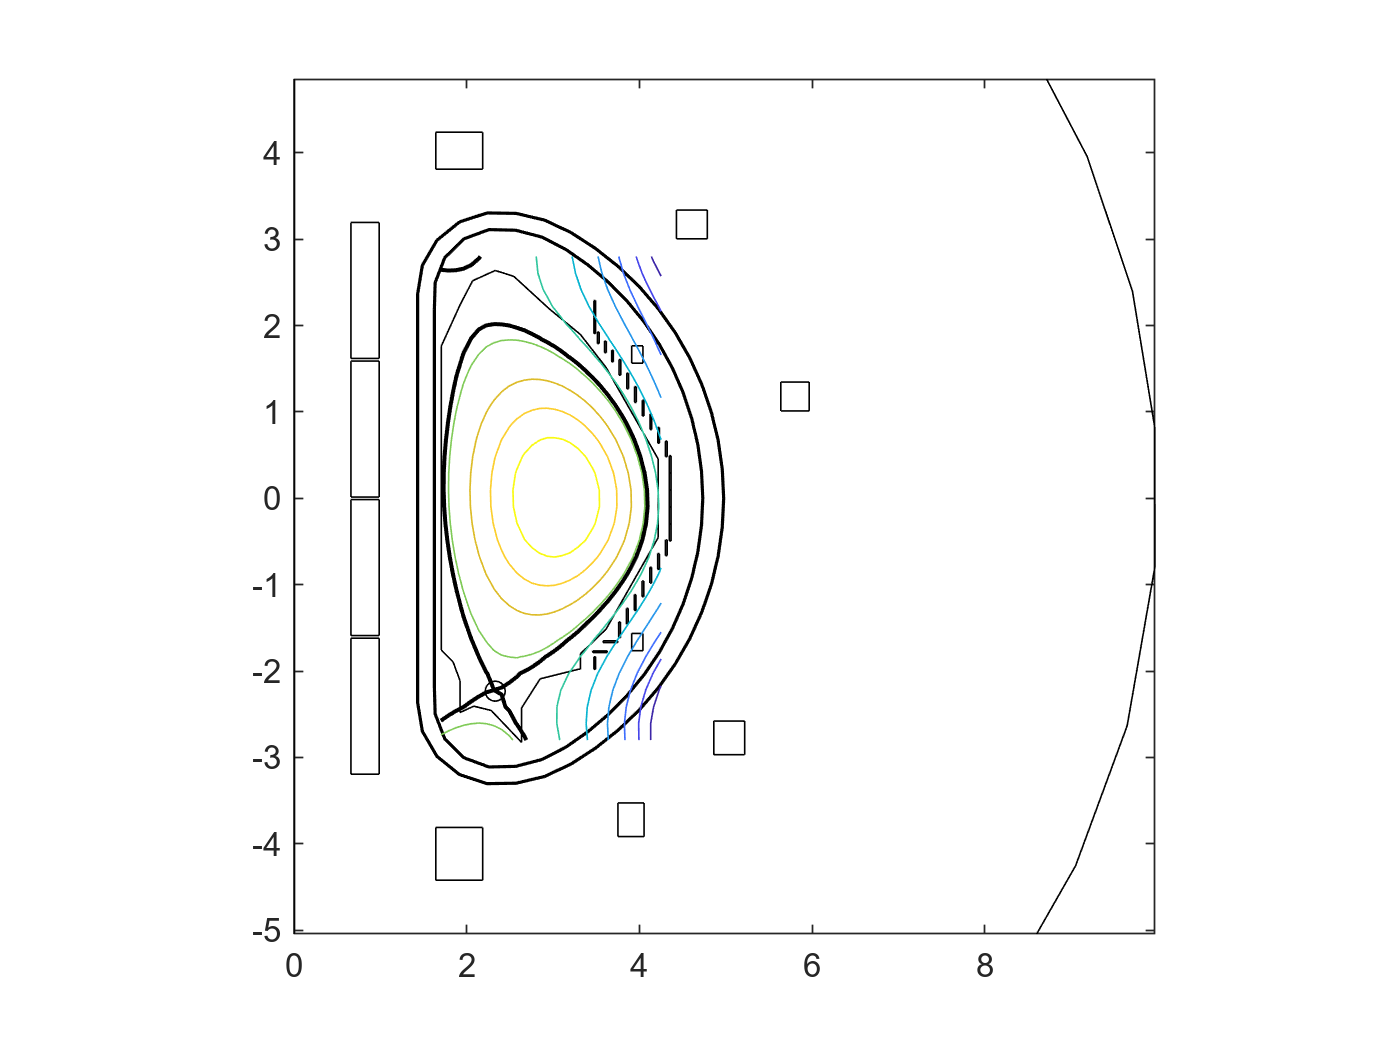

out = sim('SOF18d66.slx');

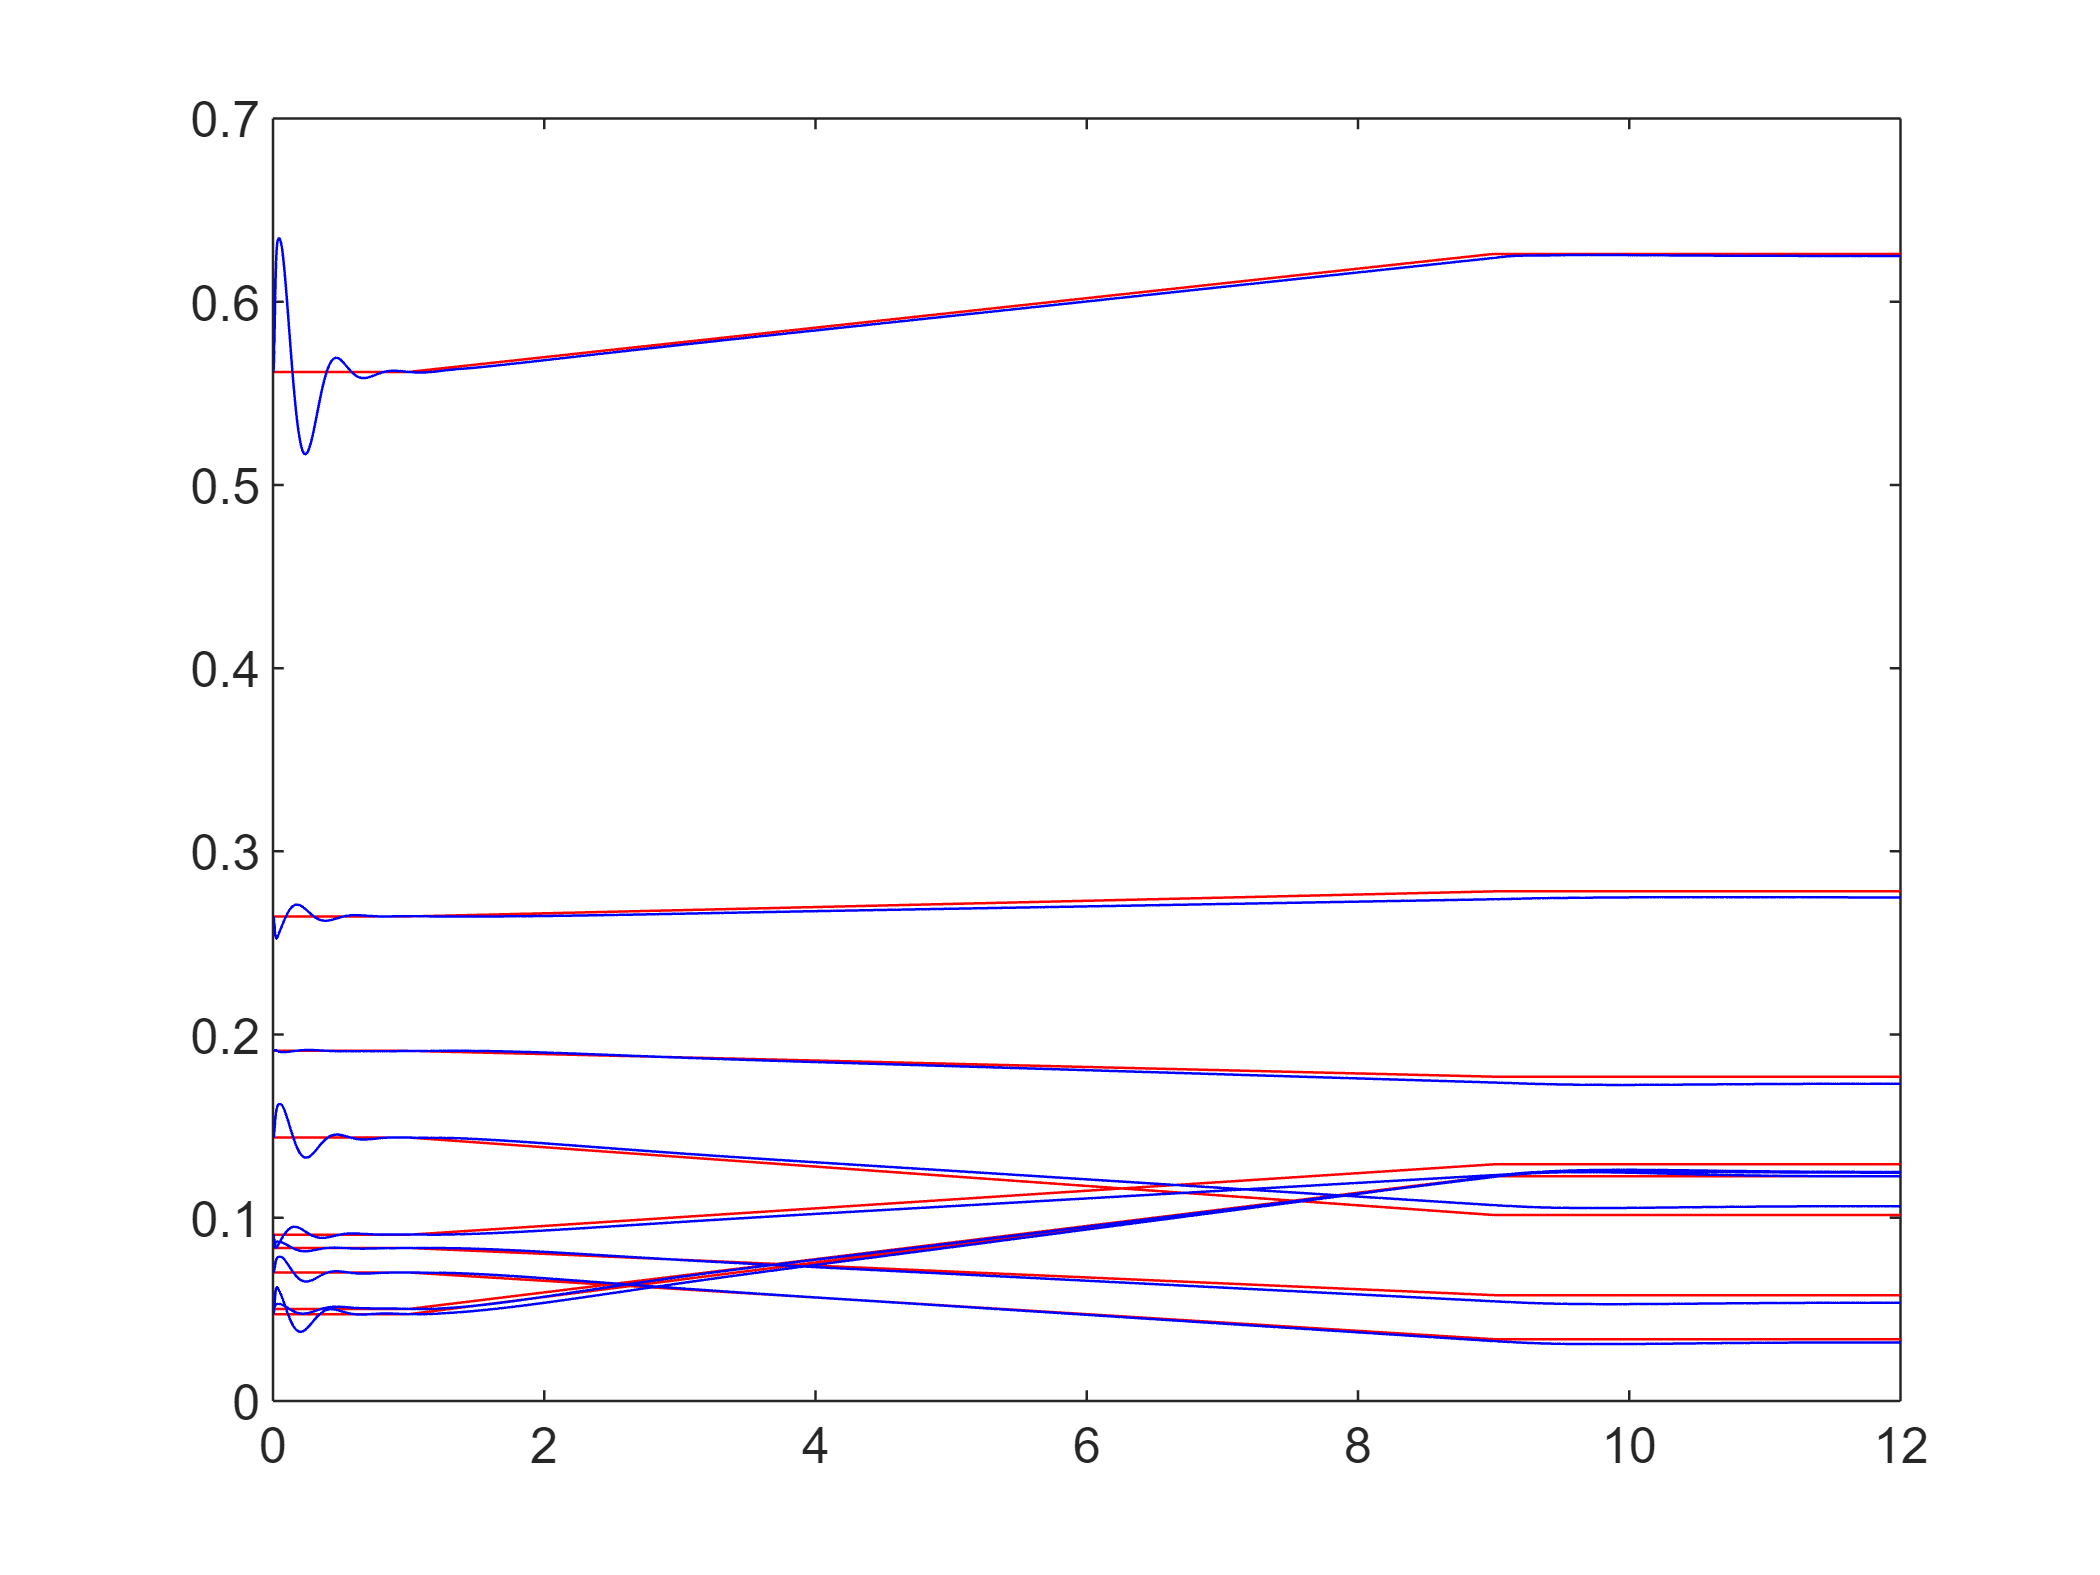

figure
plot(shp_ref.time, shp_ref.signals.values(:,1:end-2), 'r')
hold on
plot(out.Gaps.time, out.Gaps.signals.values(:,iGap), '-b')

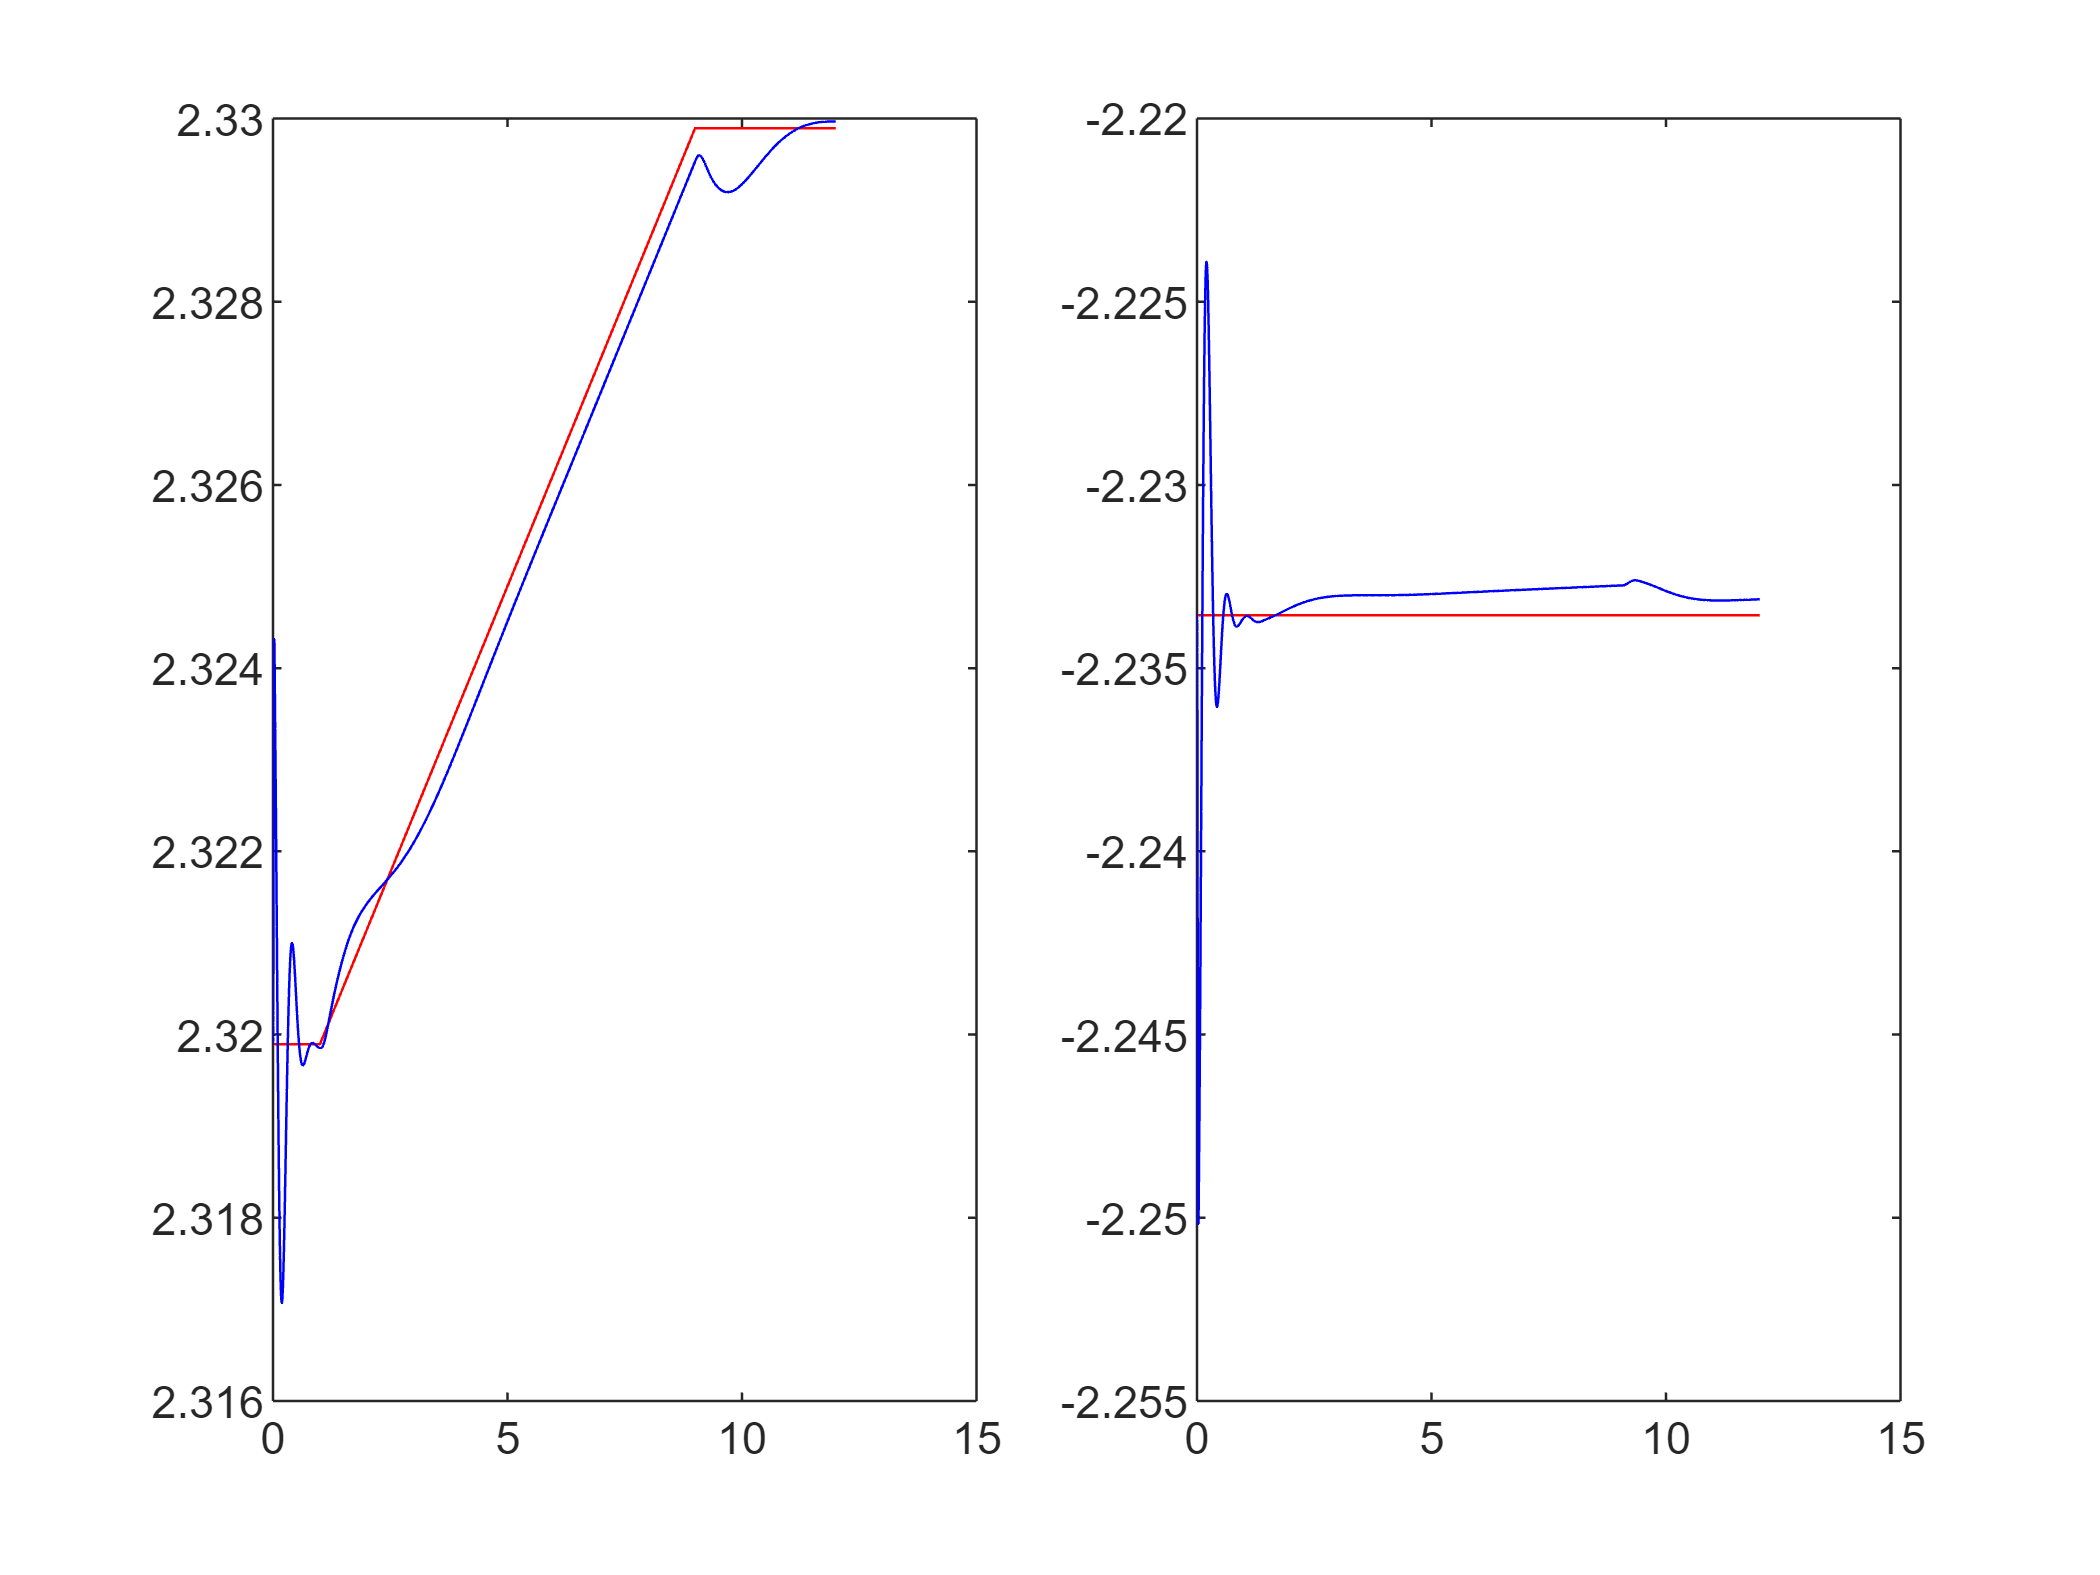

figure
subplot(121)
plot(shp_ref.time, shp_ref.signals.values(:,end-1), 'r')
hold on
plot(out.Null_Point.time, out.Null_Point.signals.values(:,1), '-b')

subplot(122)
plot(shp_ref.time, shp_ref.signals.values(:,end), 'r')
hold on
plot(out.Null_Point.time, out.Null_Point.signals.values(:,2), '-b')

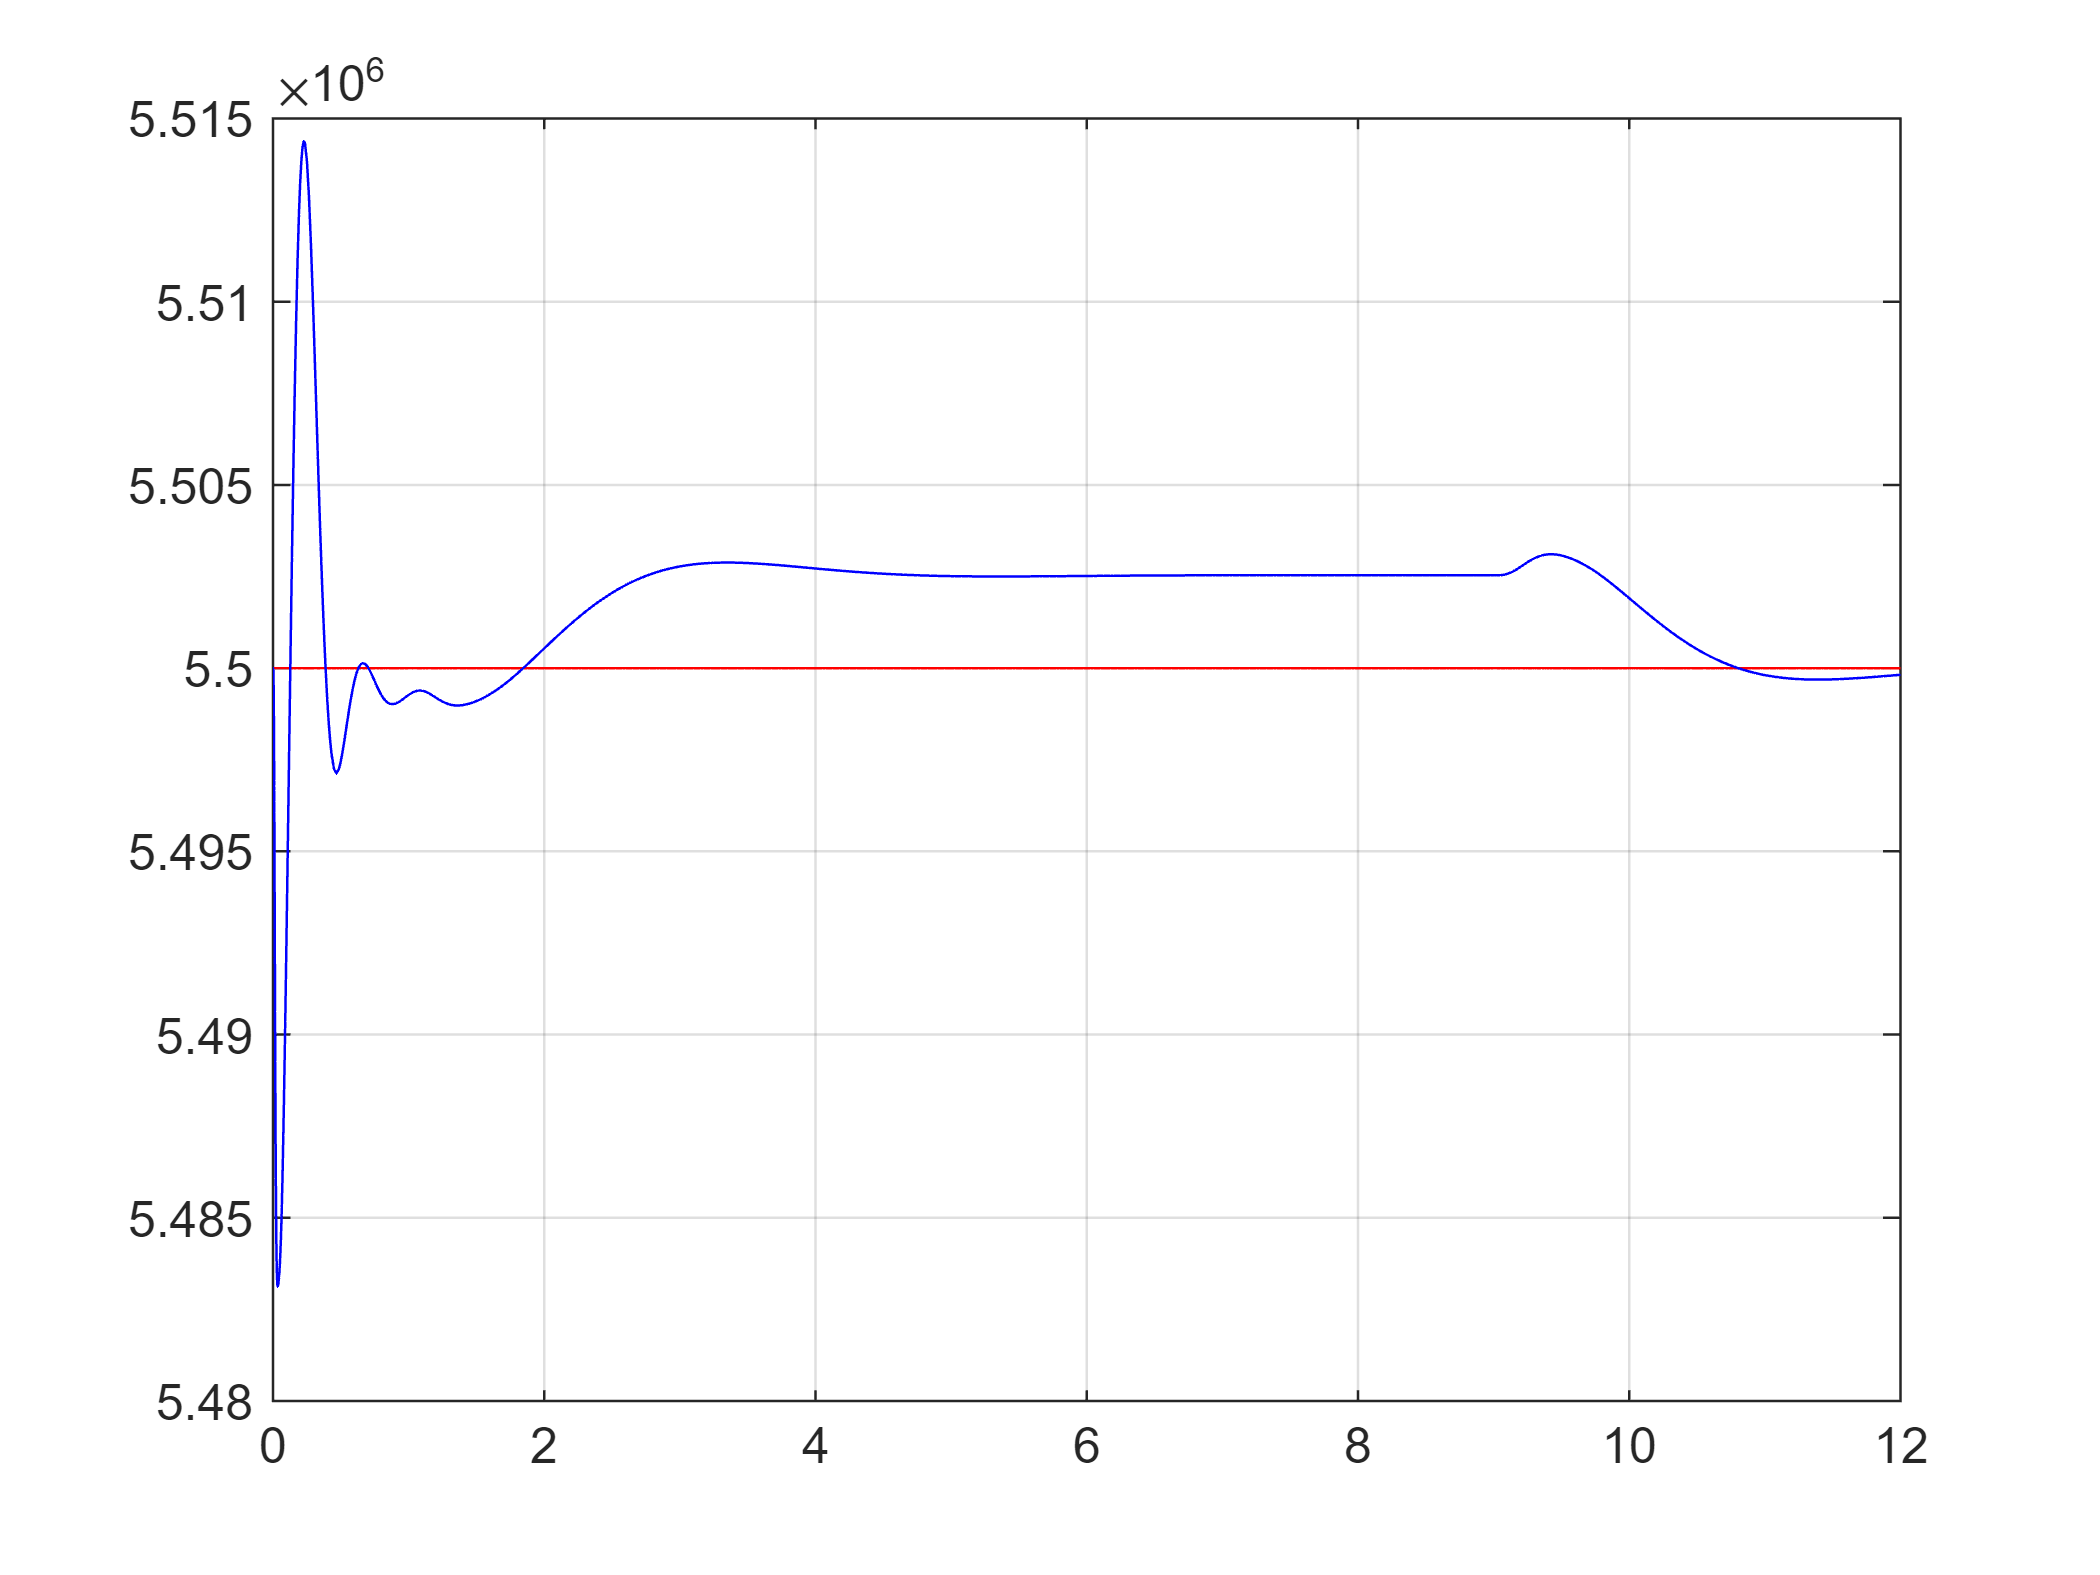

figure
plot(out.Ipl.time, out.Ipl.time*0+5.5e6,'r');
hold on, grid on
plot(out.Ipl.time, out.Ipl.signals.values,'b')

cd ..